# Riassunto Matlab  

clc
clear vars
A=3;
dt=0.001;
t=-10:dt:10;
t0=0;

#### Segnali/Filtri fondentali

- Box $\Pi \left(\frac{t}{T}\right)$ 

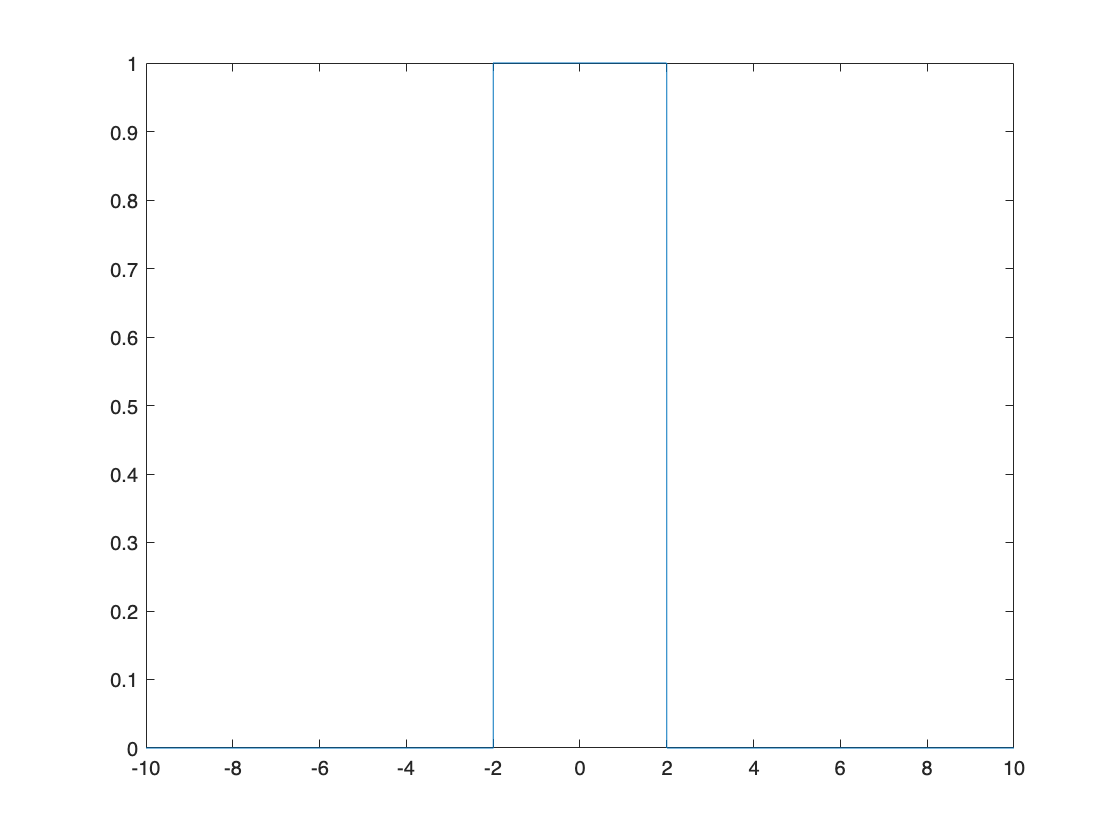

T=4;
box=zeros(size(t));
box((t-t0)>= -T/2 & (t-t0)<=T/2)=1;
figure;
plot(t,box);

- Finestra triangolare $\Lambda \left(\frac{t-t_0}{T}\right)$

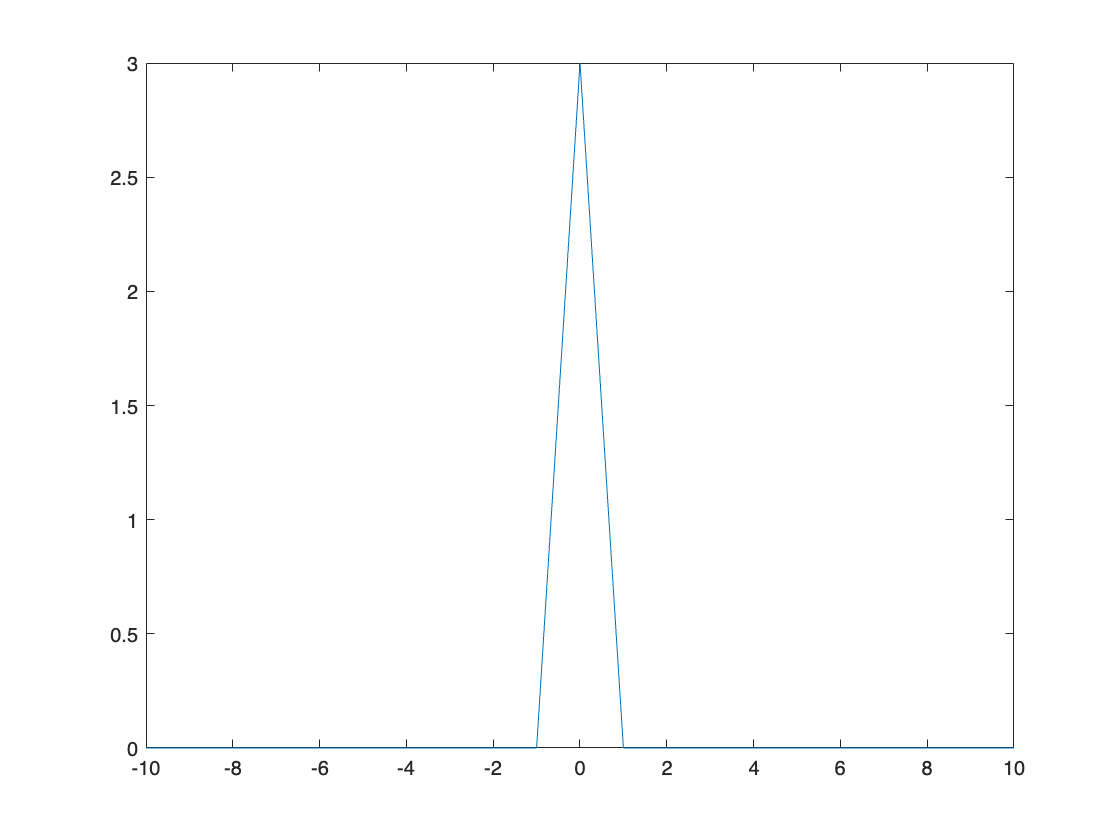

T=1;
tri=A*max(1-abs(t-t0)/T,0);
figure;
plot(t,tri);

- delta di dirac $\delta(t-t_o)$

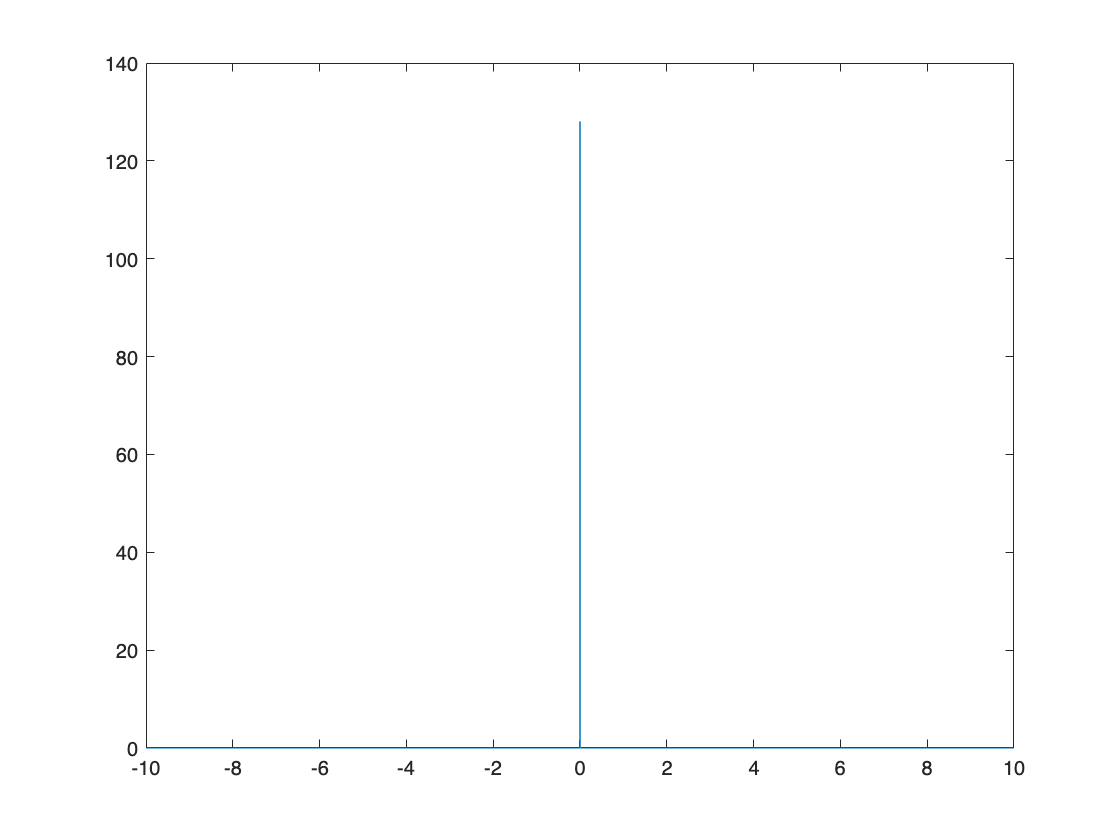

n=128;
delta=zeros(size(t));
delta((t-t0)>= -1/n & (t-t0)<=1/n)=n;
figure;
plot(t,delta);

- Seni e Coseni di frequenza fondamentale f 

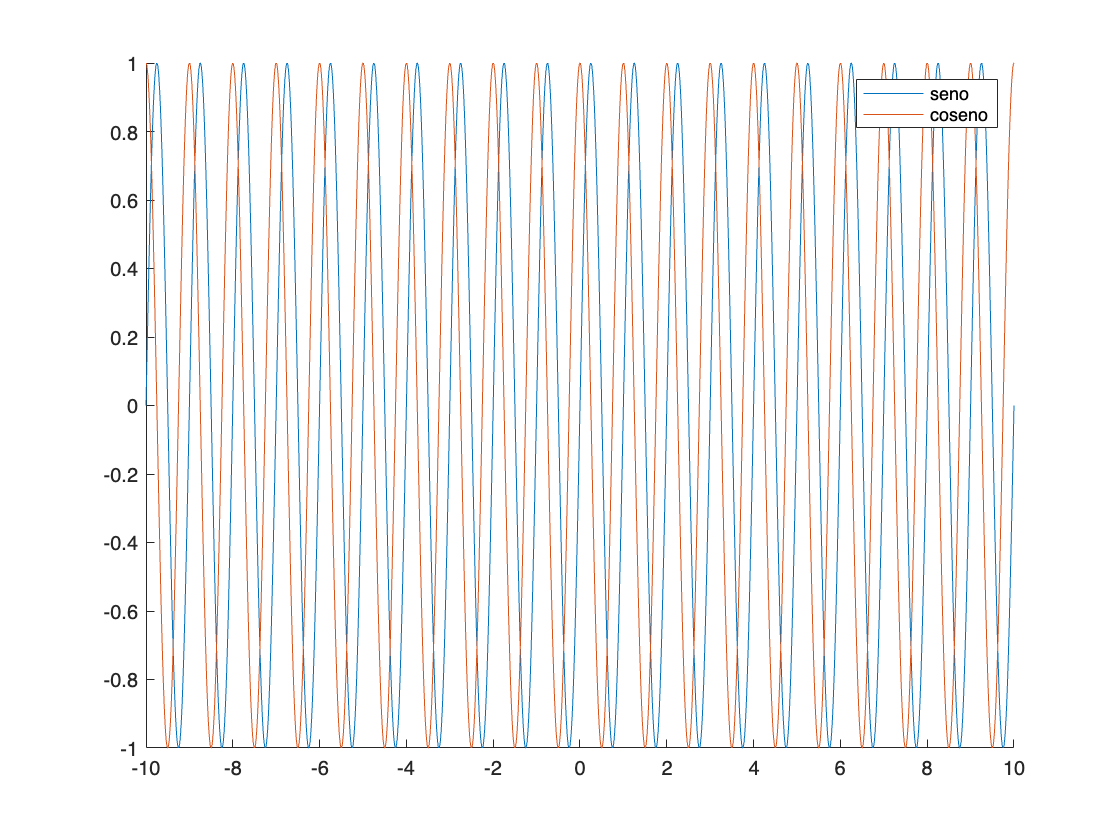

f=1;
seno=sin(2*pi*f*t);
coseno=cos(2*pi*f*t);
% vediamo come si plottano due cose nella stessa figura
figure;
hold on 
plot(t,seno)
plot(t,coseno)
legend('seno','coseno')
hold off

- Esponenziali e Potenze  ad esempio : $e^t \ ,\ (A)^t \ , t^A$

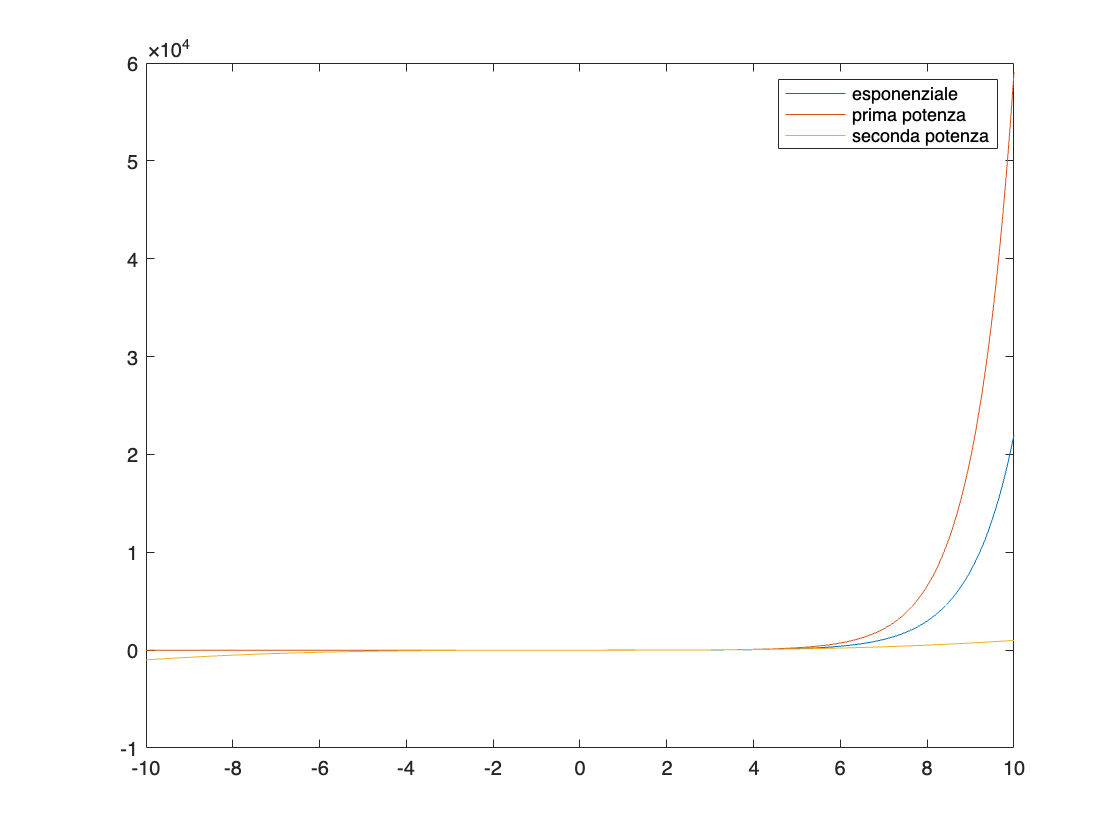

espon=exp(t);
potenza1=A.^t;
potenza2=t.^A;
figure;
%altro metodo per plottare tutto in un'unica figura
plot(t,espon,t,potenza1,t,potenza2)
legend('esponenziale','prima potenza','seconda potenza')

- Gradino $
\delta_{-1}(t-t_0) 
$ e Rampa $\delta_{-2}(t-t_0)$

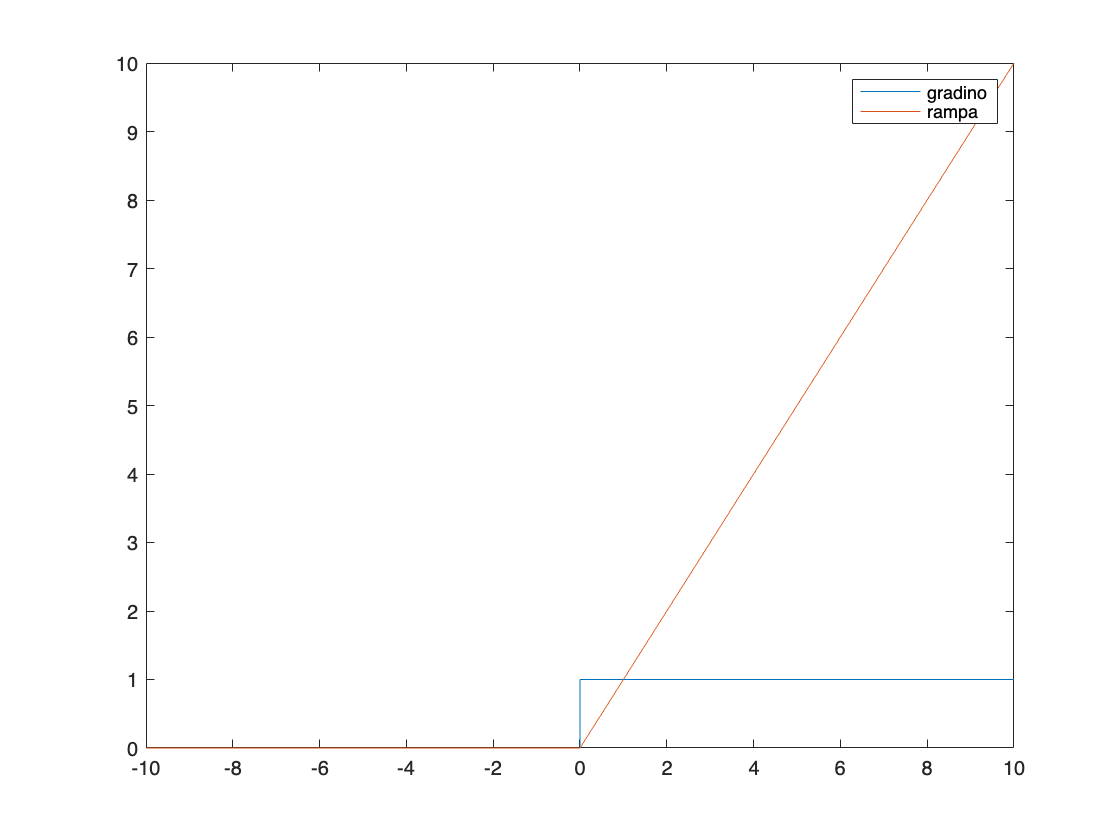

grad=zeros(size(t));
rampa=zeros(size(t));
grad((t-t0)>=0)=1;
rampa(t>=t0)=t(t>=t0)-t0;
plot(t,grad,t,rampa);
legend('gradino','rampa')

- Operazioni elementari

%Moltiplicazione 
moltplicazione=seno.*coseno;
%Diverse implimentazione di una moltiplicazione per gradino ritardato/anticipato di t0 
es1=seno.*grad;
%oppure
seno2=zeros(size(t));
seno2(t>=t0)=sin(2*pi*f*t(t>=t0));
%esempio preso da un esame 


$$\left(\frac{1}{2}\right)^t\ * \delta_{-1}(t)$$


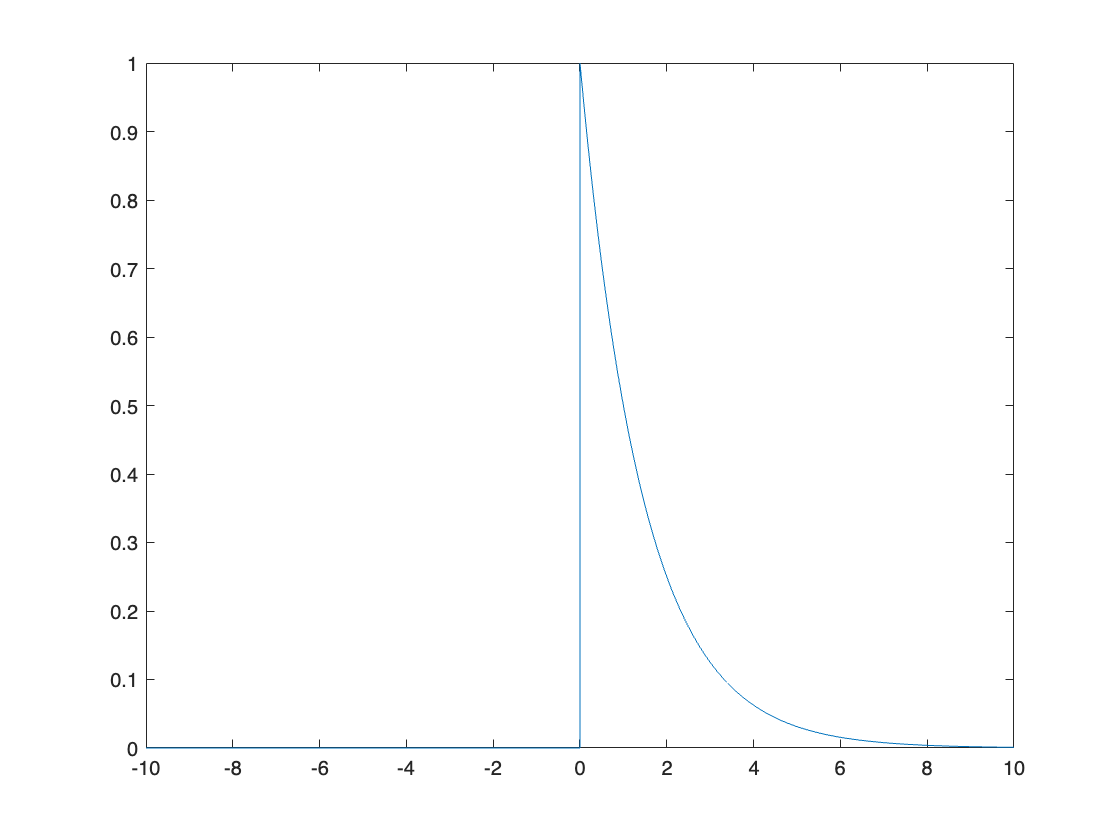

sig=zeros(size(t));
sig(t>=0)=(1/2).^t(t>=0);
plot(t,sig);

#### FILTRI

- Filtri passa basso frequenza di taglio fh e ritardato/anticipato di t0

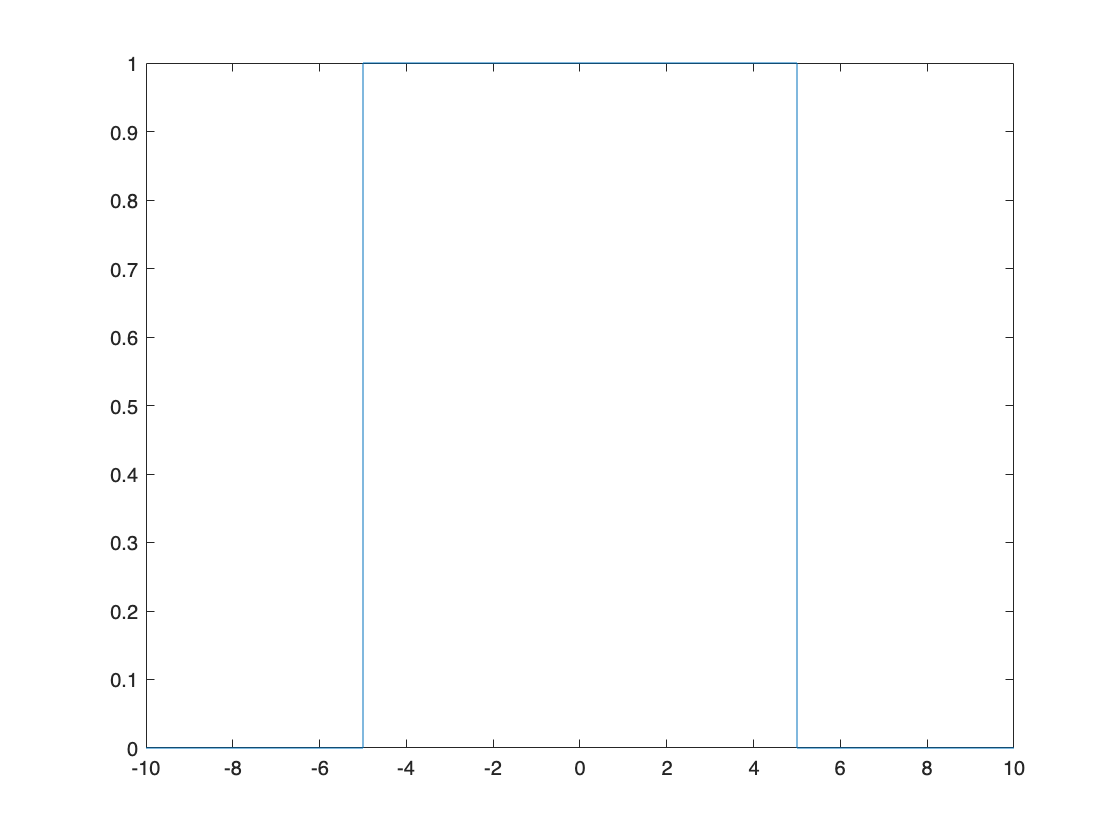

fh=5;
filtro_pbs=zeros(size(t));
filtro_pbs((t-t0)>=-fh & (t-t0)<=fh)=1;
plot(t,filtro_pbs)

- Filtri passa alto frequenza di taglio fh e ritardato/anticipato di t0

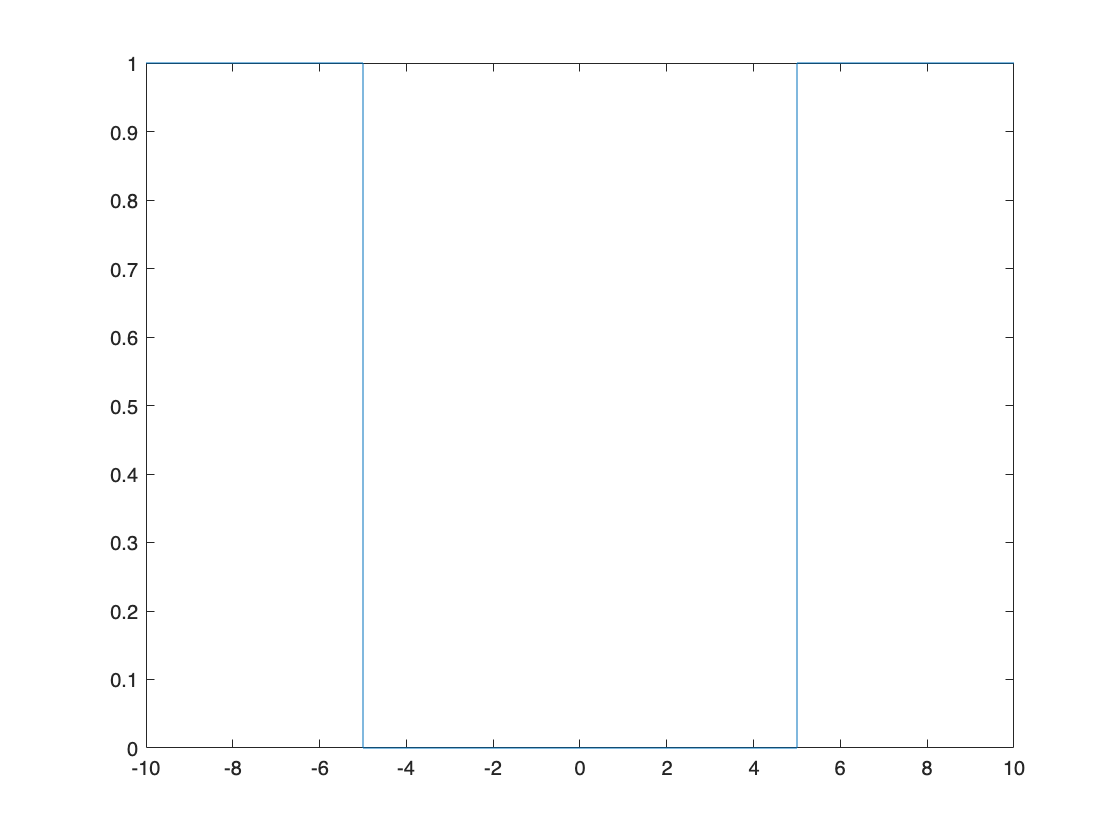

filtro_a=zeros(size(t));
filtro_a((t-t0)<=-fh | (t-t0)>=fh)=1;
plot(t,filtro_a)

- Filtro passa Banda con frequenze di taglio fc1 e fc2

fc1=2;
fc2=4;
filtro_pba=zeros(size(t));
filtro_pba((t-t0)>=fc1 & (t-t0)<=fc2)=1;
filtro_pba((t-t0)>=-fc2 & (t-t0)<=-fc1)=1;

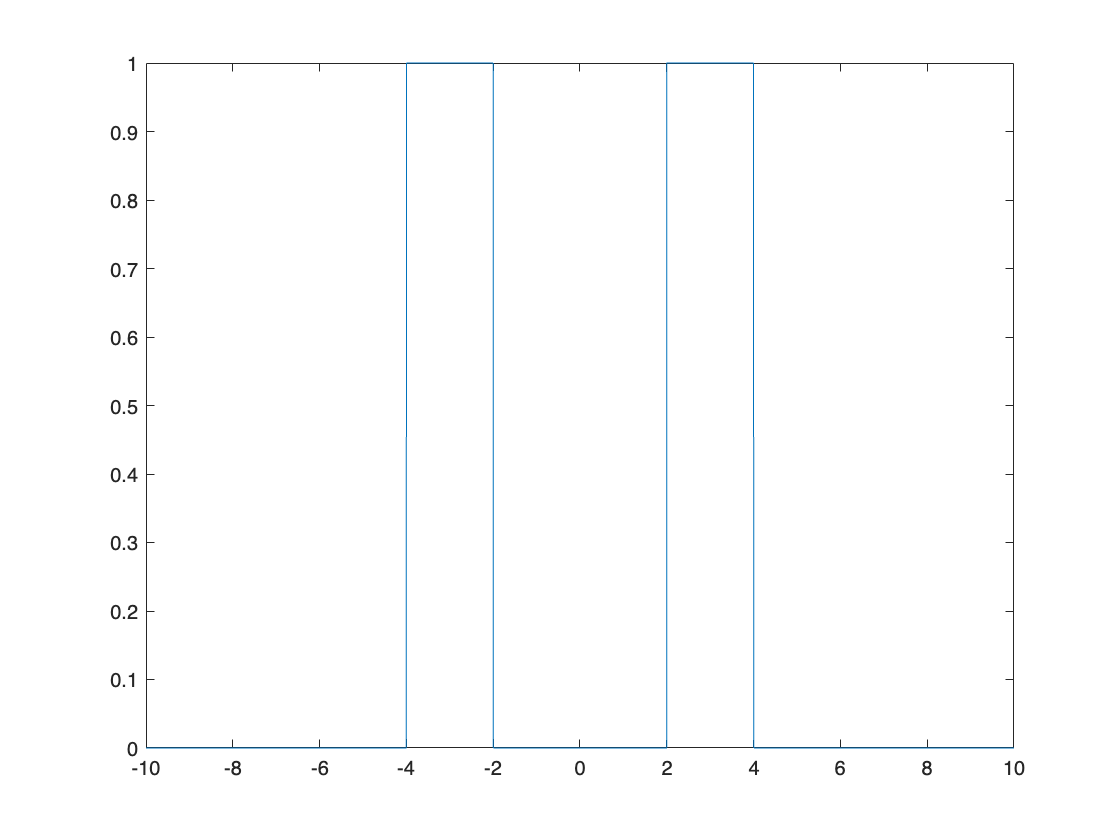

plot(t,filtro_pba);

- Filtro elimina banda 

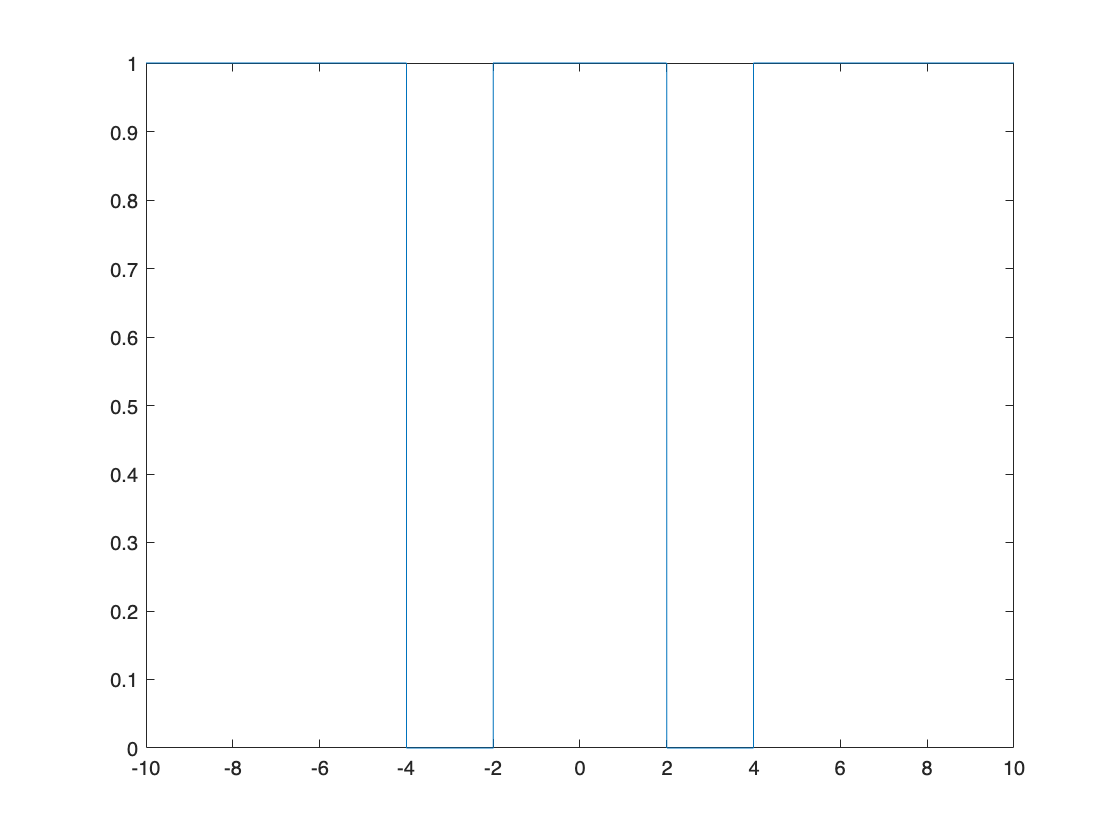

fc1=2;
fc2=4;
filtro_eb=zeros(size(t));
filtro_eb((t-t0)<=-fc2)=1;
filtro_eb((t-t0)>=-fc1 & (t-t0)<=fc1)=1;
filtro_eb((t-t0)>=fc2)=1;
plot(t,filtro_eb)

#### OPERAZIONE FONDAMENTALI

- Area Valore Medio Energia Potenza .

In questio caso il segnale di parte e un po' strano cosi vediamo come creare anche cosi un minimo piu complicate $f(x)=
\begin{cases}
e^{x} \ \ x \leq 0\\
e^{-x} \  x\geq 0
\end{cases}$

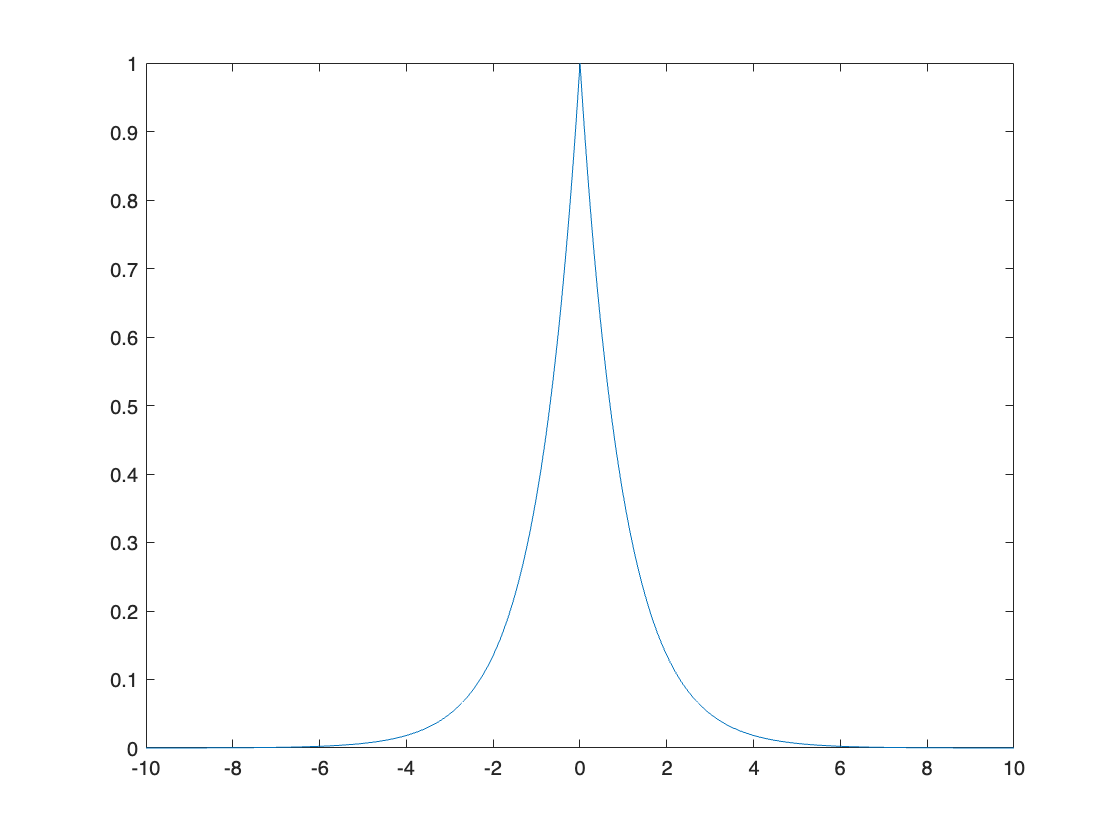

fx=zeros(size(t));
fx(t>=0)=exp(-t(t>=0));
fx(t<0)=exp(t(t<0));
figure;
plot(t,fx)

A_fx=trapz(t,fx); 
%il comando trapz effettua un'integrazione numerica e di default spacing
%tra i punti e' uno , cosa che nel nostro caso non e' vera , quindi
%dobbia indicaglierlo il primo modo e' quello appena presentato altri modi
%sono i seguenti 
%A_fx=trapz(dt,x)
%A_fx=trapz(x)*dt
Vm_fx=A_fx/(2*t(end)+1) % t(end) prende il valore finale di t 

Vm_fx = 0.0952

E_fx=trapz(t,abs(fx).^2)

E_fx = 1.0000

Pm_fx=E_fx/(2*t(end)+1)

Pm_fx = 0.0476

- Convoluzione 

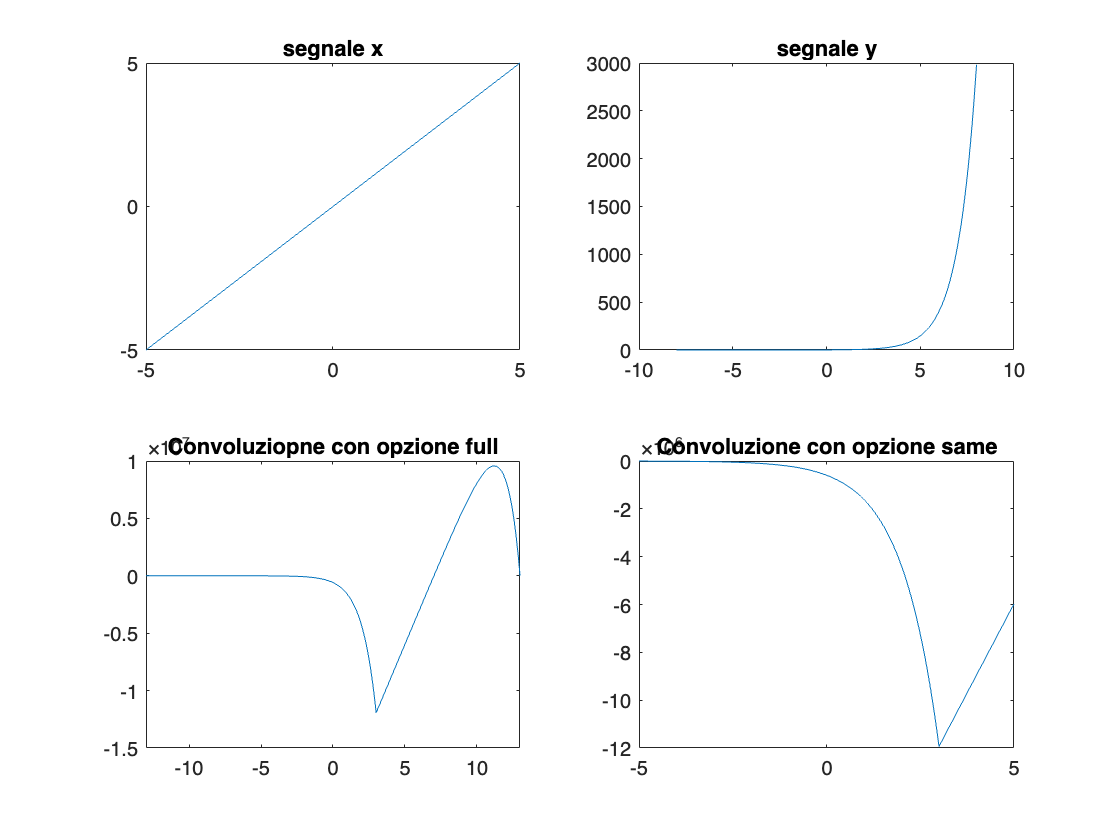

%{il comando per svolgere la convoluzione su matlab e conv() , il comando prende in input due vettori(u,v) e un'opzione tra full , same e valid
%full che crea un vettore che lunghezza pari e length(u)+length(v)-1 
%same che resistuisce un vettore della stessa lunghezza di u 
%valid restituisce solo la parte di convoluzione calcolata senza i bordi di riempimento con zeri
%}
t1=-5:dt:5;
t2=-8:dt:8;
t_conv=-(5+8):dt:(5+8); % vediamo come il tempo della convoluzione  viene creato sommando gli estremi dei tempi dei due segnali 
x=t1;
y=exp(t2);
conv_same=conv(x,y,"same");
conv_full=conv(x,y,'full');
subplot(221)
plot(t1,x)
title('segnale x')
subplot(222)
plot(t2,y)
title('segnale y')
subplot(223)
plot(t_conv,conv_full)
title('Convoluziopne con opzione full')
subplot(224)
plot(t1,conv_same)
title('Convoluzione con opzione same')

- Correlazione (cross e auto)

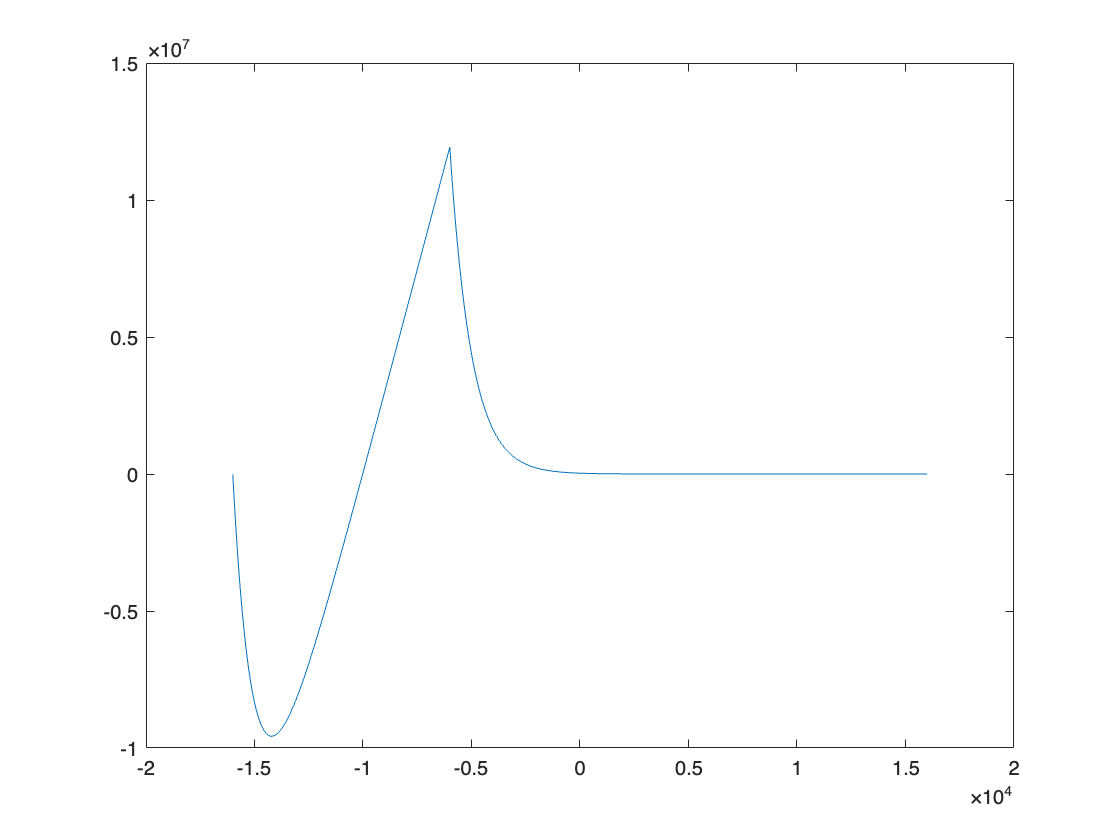

%il comando per la correlazione e xcorr e da come output [rxy,lags] dove
%rxy e' il vettore contenente le crosscorrelazione e lags e il vettore dei
%ritardi utile ad esempio per plottare la convoluzione 
[Rxy,lags]=xcorr(x,y);  % La convoluzione non gode della proprietà commutativa
figure;
plot(lags,Rxy);

### DOMINIO DELLA FREQUENZA

In quest'ultima parte vediamo come nel dominio della frequenza come plottare ampiezza e fase della risposta in frequenza , come filtrare un segnale e in fine come tornare al dominio del tempo , inoltre avremo principalmente due casi uno in cui la trasformata sara centrata  rispetto alle frequenze  (mettero un pedice c) e un altro in cui la frequenza non lo sara.  

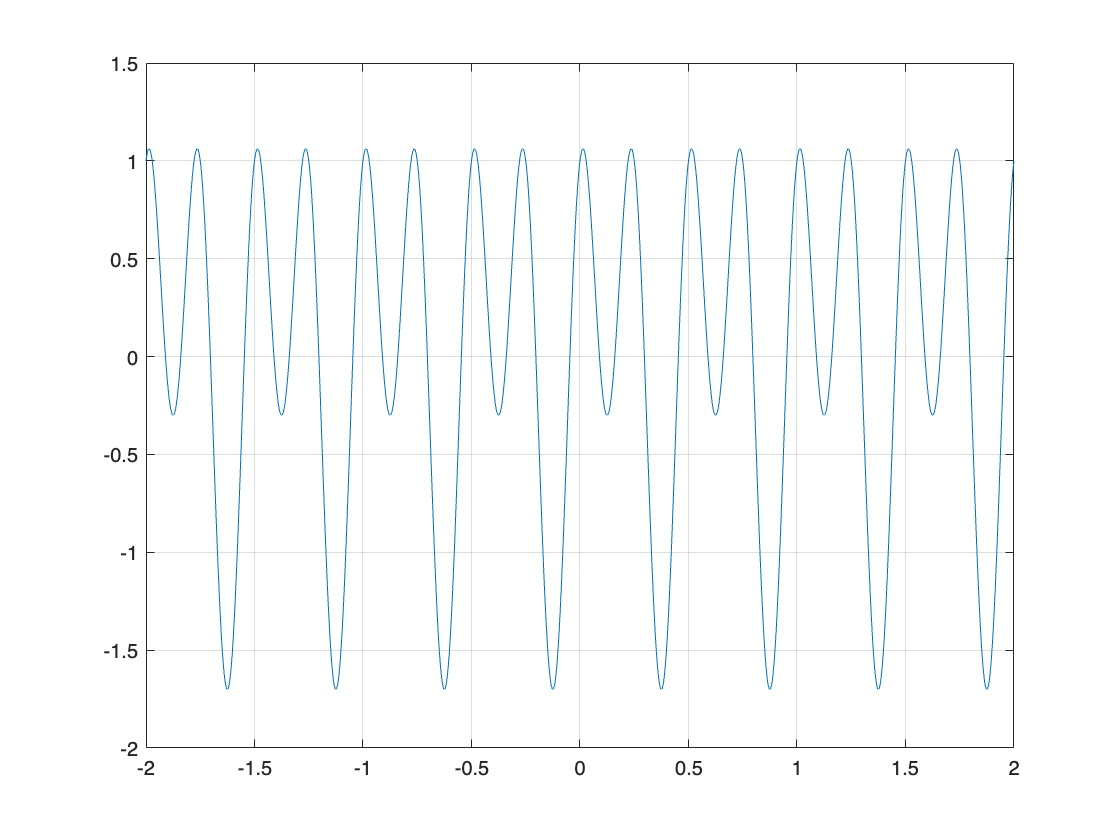

fc=1/dt;
fy=0.7*cos(2*pi*2*t - pi/2) + cos(2*pi*4*t );
figure
plot(t,fy)
grid on 
xlim([-2,2])

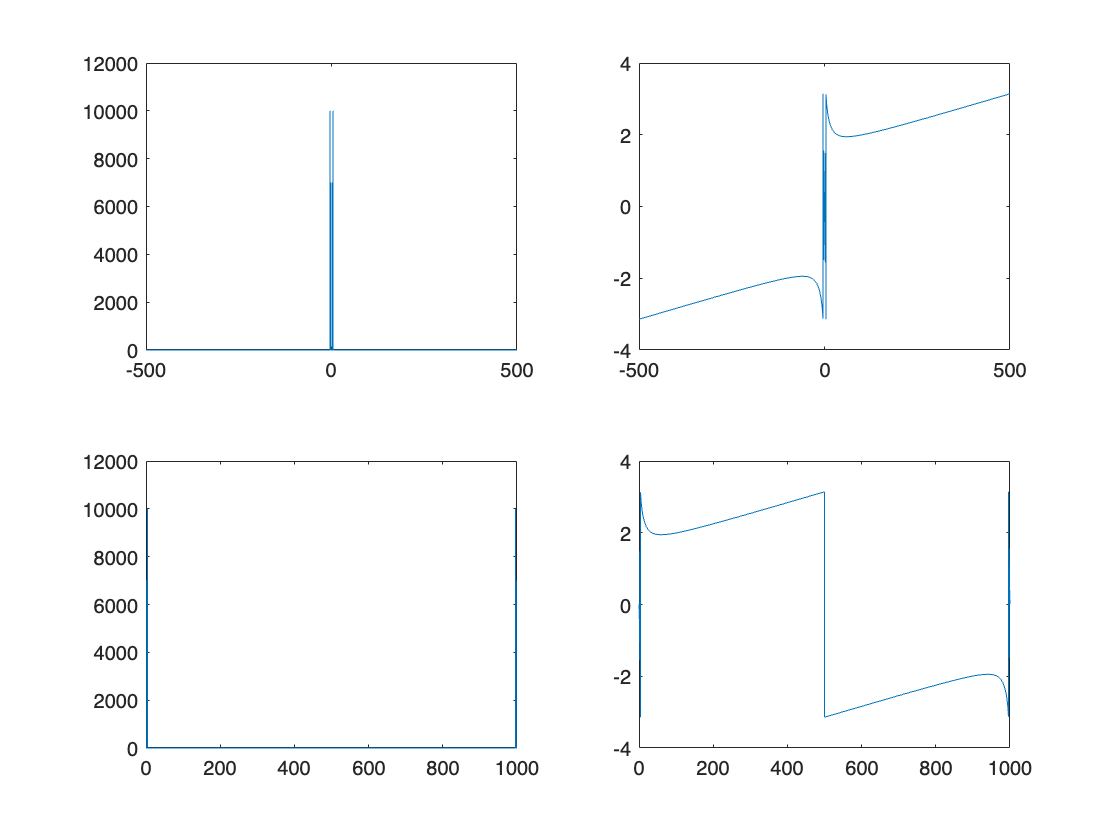

trasfx_c=fftshift(fft(fy));
trasfx=fft(fy);
step=fc/length(trasfx);
t_trasf_c=-fc/2:step:fc/2-step;
t_trasf=0:step:fc-step;
figure
subplot(221)
plot(t_trasf_c,abs(trasfx_c));
subplot(222)
plot(t_trasf_c,angle(trasfx_c));
subplot(223)
plot(t_trasf,abs(trasfx));
subplot(224)
plot(t_trasf,angle(trasfx));

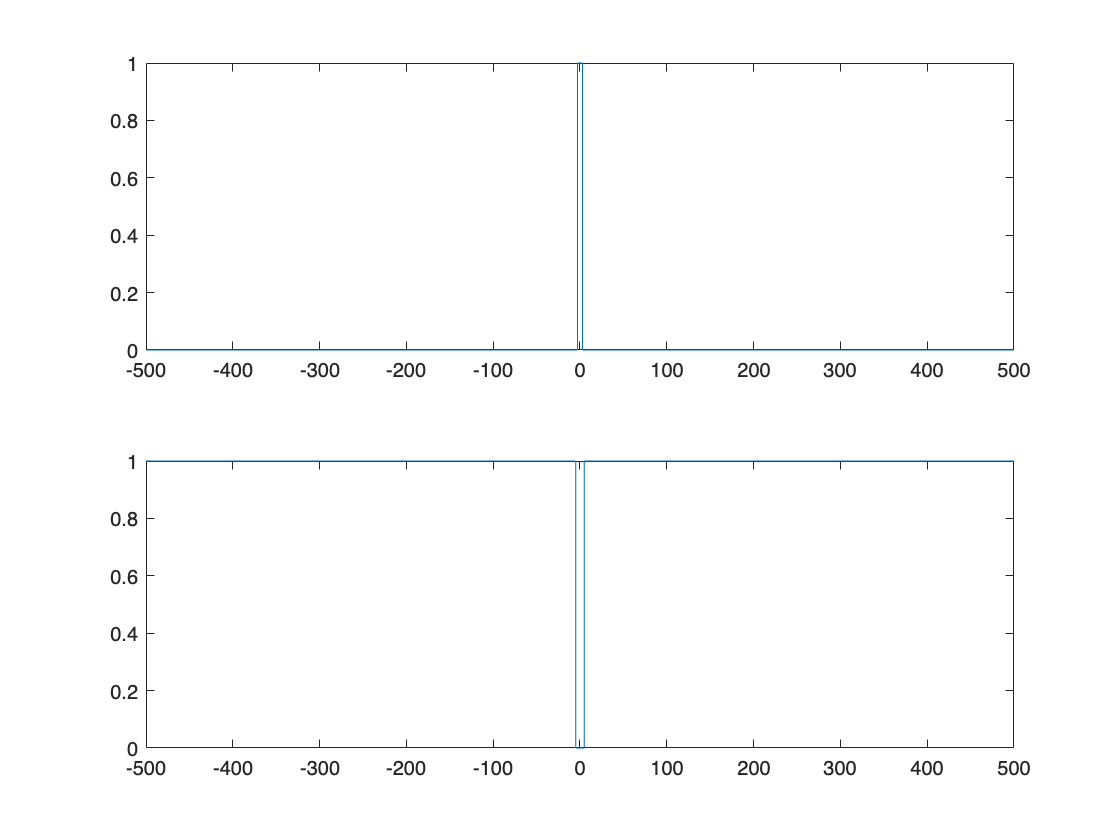

% Ora filtriamo unicamente la trasformata centrata attraverso un filtro
% passa basso e un filtro passa alto
filtro1=zeros(size(t_trasf_c));
filtro2=zeros(size(t_trasf_c));
filtro1(t_trasf_c >= -3 & t_trasf_c <=3)=1;
filtro2(t_trasf_c<=-5 | t_trasf_c>=5)=1;
% plottiamo i due filtri nel dominio della frequenza 
figure;
subplot(211)
plot(t_trasf_c,filtro1);
subplot(212)
plot(t_trasf_c,filtro2);

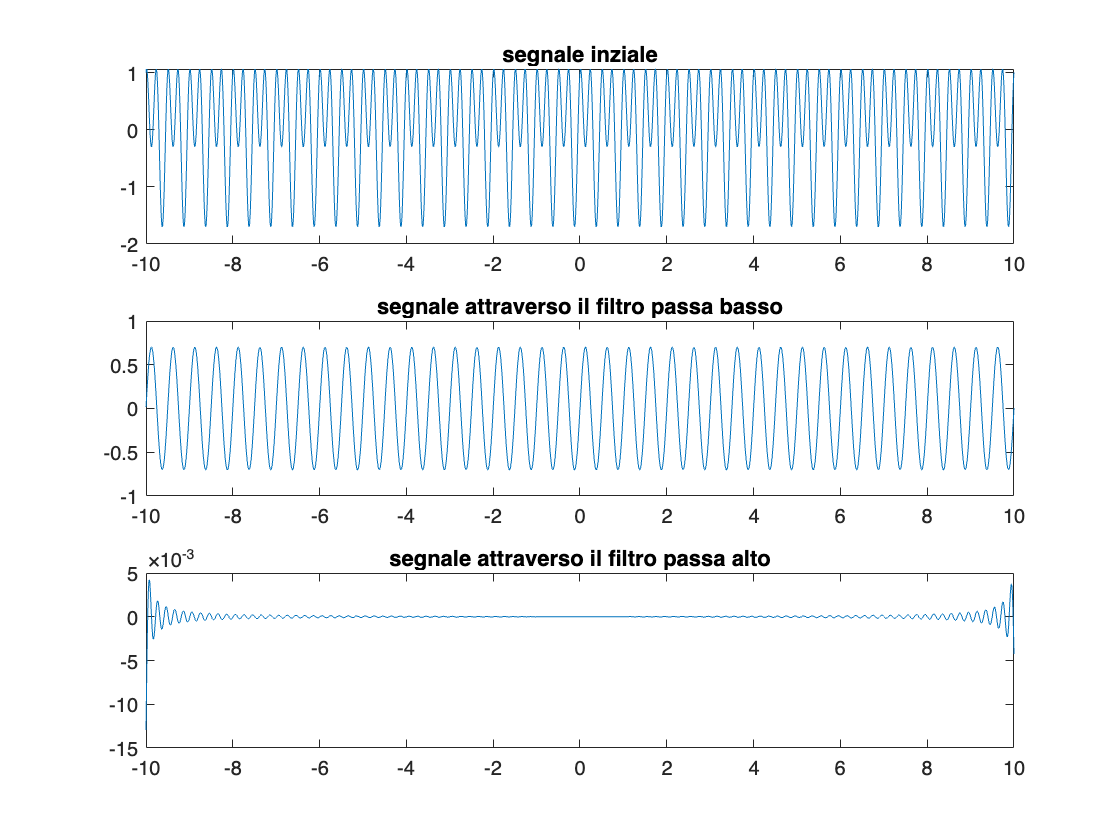

trasf1=trasfx_c.*filtro1;
trasf2=trasfx_c.*filtro2;
% Ora ritorniamo nel dominio del tempo e plotiamo il segnale inziale e i
% due segnali filtrati 
fy1=ifft(ifftshift(trasf1));
fy2=ifft(ifftshift(trasf2));
figure
subplot(311)
plot(t,fy)
title('segnale inziale');
subplot(312)
plot(t,real(fy1))
title('segnale attraverso il filtro passa basso');
subplot(313)
plot(t,real(fy2))
title('segnale attraverso il filtro passa alto');

- FFT con zero padding 

%Scopriamo quanti campioni ha il segnale fy
N=length(fy)

N = 20001

%Ora creiamo una trasforma zero padded che utilizzo N=40001
N_zero=40001

N_zero = 40001

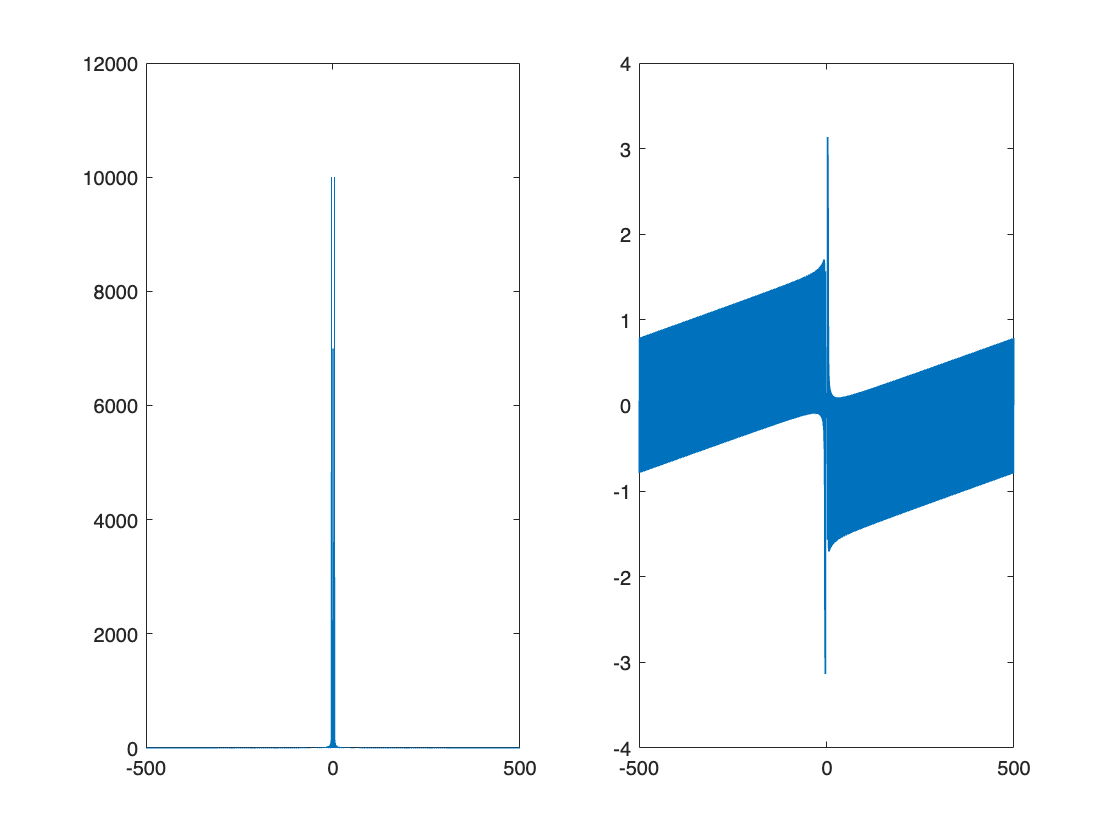

trasf_zero=fftshift(fft(fy,N_zero));
step_zero=fc/length(trasf_zero);
t_zero=-fc/2:step_zero:fc/2-step_zero;
figure;
subplot(121)
plot(t_zero,abs(trasf_zero))
subplot(122)
plot(t_zero,angle(trasf_zero))

% esiste anche un altro metodi per creare la trasformata zero padded
% aggiungo zeri direttamente alla funzione fy
fy_zero=[fy,zeros(1,N_zero-N)];
disp(['Lunghezza del segnale fy_zero : ',num2str(length(fy_zero))]);

Lunghezza del segnale fy_zero : 40001


%Quindi abbiamo concatenato il segnale f_y con uno numero di zeri pari alla
%differenza nella lunghezza del segnale zero padded e del segnale normale 
figure;
subplot(121)
plot(t_zero,abs(fftshift(fft(fy_zero))));
subplot(122)
plot(t_zero,angle(fftshift(fft(fy_zero))));

Vediamo che i due metodi sono identifici 